% MMI - 503/603 Basic Filter Examples
% These example demonstrates how to generate basic filter types.

% Author: Dr. Justin D. Mathew, Ph.D
% Email: jdm423@miami.edu

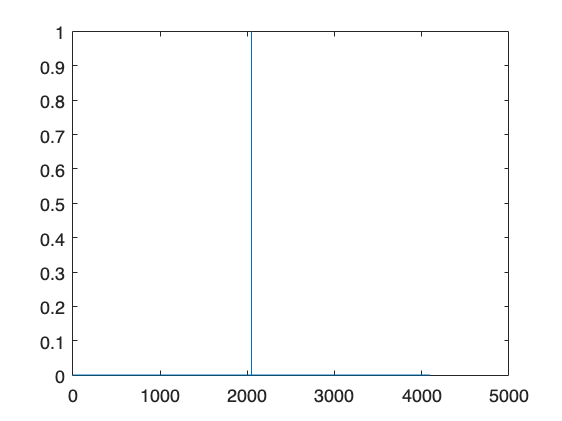

% Create a dirac delta signal
fs = 48000;
buffer_size = 4096;
dirac_delta = zeros(buffer_size,1);
dirac_delta(buffer_size/2) = 1;

figure;
plot(dirac_delta);

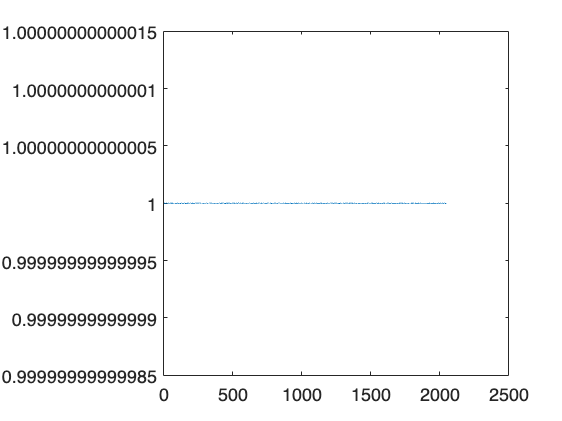

% Create a magnitude response for your desired filter
fft_dd = fft(dirac_delta, buffer_size);

figure;
plot(abs(fft_dd(1:(buffer_size/2))));

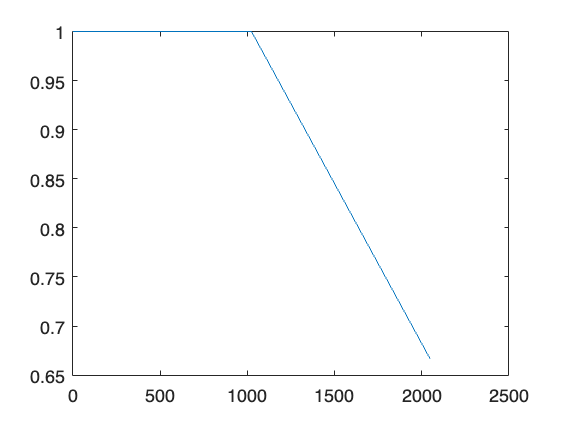


slope = linspace(1,0, 3*buffer_size/4+1);
slope = complex(slope);
fft_dd(buffer_size/4:end) = fft_dd(buffer_size/4:end).*slope';

figure;
plot(abs(fft_dd(1:buffer_size/2)));

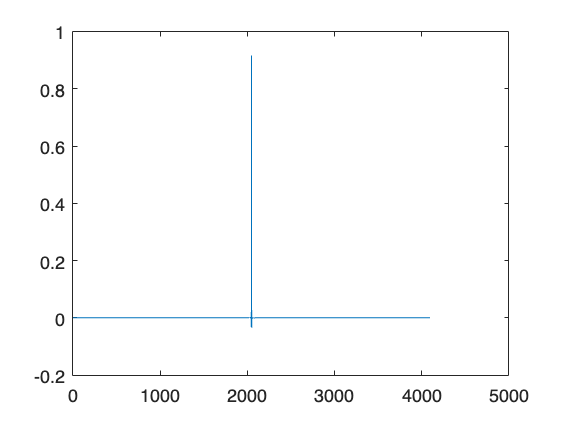


% convert fft_dd back into the time domain
lpf_ir = ifft(fft_dd,buffer_size, 'symmetric');

figure;
plot(lpf_ir);

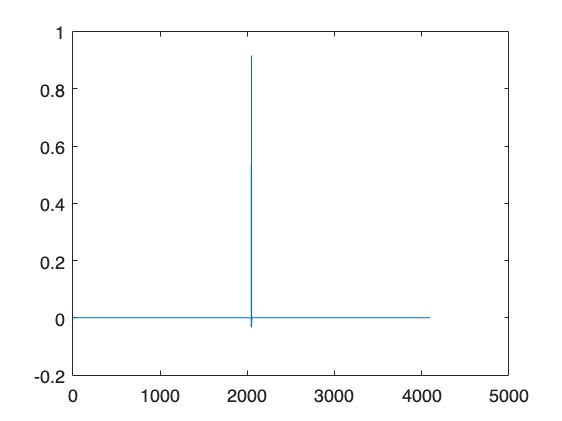


% conduct time based convolution
lpf_dd = conv(dirac_delta,lpf_ir,"same");
figure;
plot(lpf_dd);

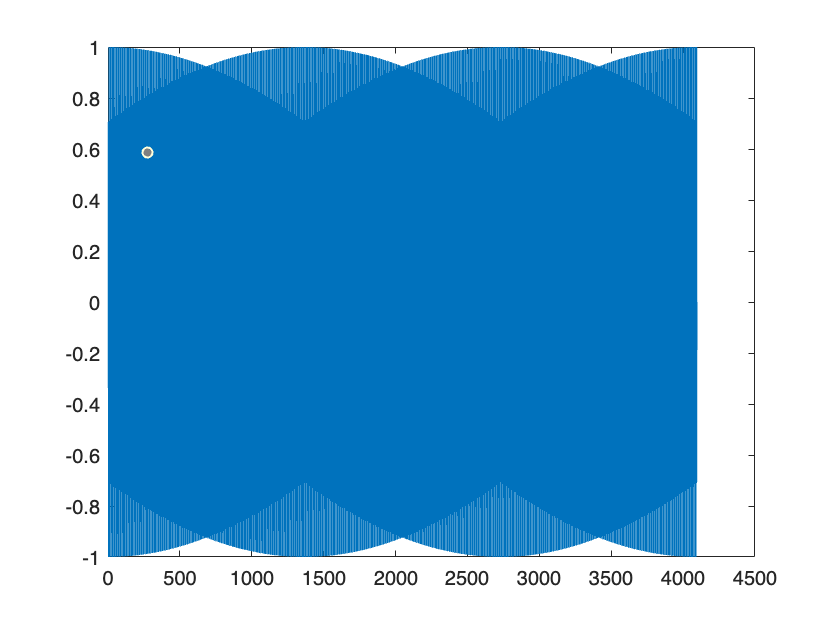

% Frequency based convolution
t = linspace(0,buffer_size/48000,buffer_size);
sin_tone = sin(2*pi*18000*t);
figure;
plot(sin_tone);

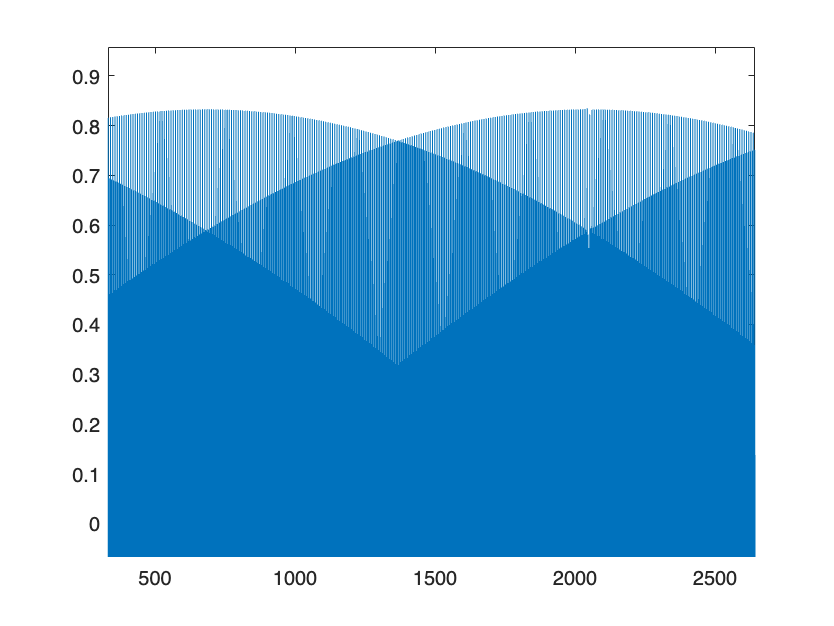


fft_st = fft(dirac_delta, buffer_size);
freq_conv = fft_st'.*fft_dd;
lpf_sin_tone = ifft(freq_conv,buffer_size,'symmetric');

figure;
plot(lpf_sin_tone);



figure;
subplot(2,1,1)
title('Time Based Convolution')
plot(lpf_dd);

subplot(2,1,2)
title('Frequency Based Convolution')
plot(lpf_sin_tone);

% Time Delay Filters
%% CHOOSE A DIFFERENT SONG HERE
[wav, fs] = audioread("Ritviz Remix.wav");
wav = wav(:,1) + wav(:,2);
wav = wav(1:10*fs,1);

buffer_size = 4096;

wav_buffers = buffer(wav, buffer_size);

f_center = fs/4;
Q = 0.4;
gain = -12.0;
delays = [0,0,0,0];

output = zeros(size(wav_buffers, 1)*size(wav_buffers,2),1);

for i = 1:size(wav_buffers, 2)
    start_ind = (i-1)*4096 + 1; 
    stop_ind = start_ind + 4095;
    [output(start_ind:stop_ind,1), delays] = funkyfiltEQ(wav_buffers(:,i), f_center, Q, gain, delays, fs);

end

soundsc(output, fs);
